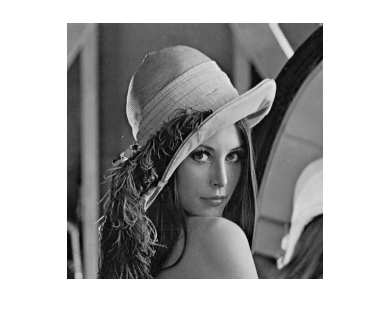

lenaImg = imread("Lena.gif");
imshow(lenaImg)

doubleLenaImg = im2double(lenaImg)

doubleLenaImg =     0.5373    0.5333    0.5216    0.5333    0.5412    0.5255    0.5255    0.5176    0.5176    0.5412    0.5059    0.5137    0.5176    0.4980    0.5059    0.5059    0.5098    0.5137    0.5412    0.5412    0.5569    0.5725    0.5922    0.5922    0.5843    0.5804    0.5608    0.5255    0.4667    0.4627    0.3529    0.3137    0.2510    0.2431    0.2392    0.2706    0.2784    0.2863    0.2863    0.2902    0.3059    0.2902    0.2980    0.3098    0.2980    0.2941    0.3059    0.2980    0.3059    0.3059
    0.5373    0.5333    0.5216    0.5333    0.5412    0.5255    0.5255    0.5176    0.5176    0.5412    0.5059    0.5137    0.5176    0.4980    0.5059    0.5059    0.5098    0.5137    0.5412    0.5412    0.5569    0.5725    0.5922    0.5922    0.5843    0.5804    0.5608    0.5255    0.4667    0.4627    0.3529    0.3137    0.2510    0.2431    0.2392    0.2706    0.2784    0.2863    0.2863    0.2902    0.3059    0.2902    0.2980    0.3098    0.2980    0.2941    0.3059    0.2980   

LPF = ones(3,3)/9

LPF =     0.1111    0.1111    0.1111
    0.1111    0.1111    0.1111
    0.1111    0.1111    0.1111


filteredLenaImg = imfilter(doubleLenaImg, LPF, 'replicate')

filteredLenaImg =     0.5359    0.5307    0.5294    0.5320    0.5333    0.5307    0.5229    0.5203    0.5255    0.5216    0.5203    0.5124    0.5098    0.5072    0.5033    0.5072    0.5098    0.5216    0.5320    0.5464    0.5569    0.5739    0.5856    0.5895    0.5856    0.5752    0.5556    0.5176    0.4850    0.4275    0.3765    0.3059    0.2693    0.2444    0.2510    0.2627    0.2784    0.2837    0.2876    0.2941    0.2954    0.2980    0.2993    0.3020    0.3007    0.2993    0.2993    0.3033    0.3033    0.3007
    0.5355    0.5303    0.5277    0.5307    0.5307    0.5272    0.5194    0.5172    0.5224    0.5190    0.5163    0.5098    0.5081    0.5068    0.5037    0.5072    0.5089    0.5194    0.5298    0.5455    0.5569    0.5734    0.5847    0.5887    0.5852    0.5752    0.5547    0.5168    0.4810    0.4235    0.3717    0.3046    0.2684    0.2440    0.2488    0.2606    0.2749    0.2815    0.2858    0.2928    0.2941    0.2954    0.2967    0.2980    0.2972    0.2963    0.2963    0.3002 

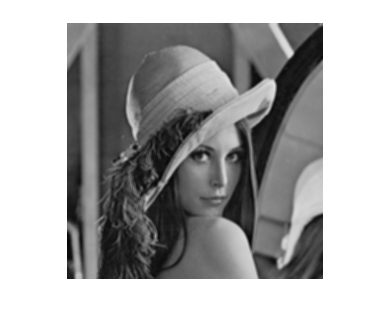

imshow(filteredLenaImg)

lenaPsnr = psnr(doubleLenaImg, filteredLenaImg, 1)

lenaPsnr = 29.2951